## **Przetwarzanie Sygnałów Cyfrowych**

# **Dyskretna transformacja Fouriera**

## Jan Rosa 410269 AiR

### Ćwiczenie 1

clear all; close all
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
w1 = 2*pi*f1;
x1 = A1*sin(w1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);%<uzupelnij>;
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   1.2341e-13



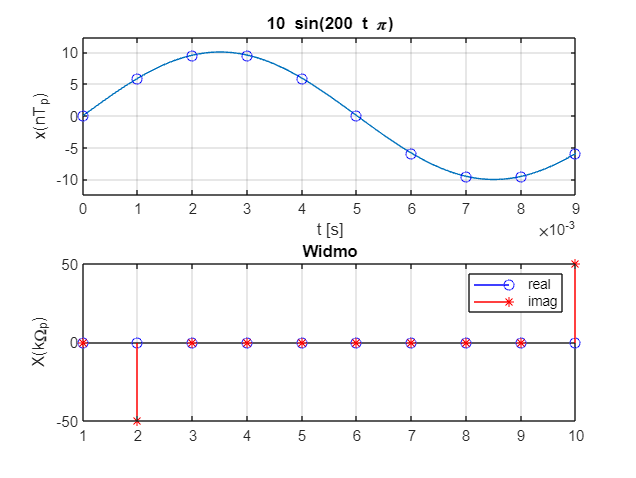

figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
stem(real(Xk),'ob'); grid on, hold on
stem(imag(Xk),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

### Zadanie 2

clear all; close all
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
w1 = 2*pi*f1;
x1 = A1*sin(w1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);%<uzupelnij>;
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   1.2341e-13



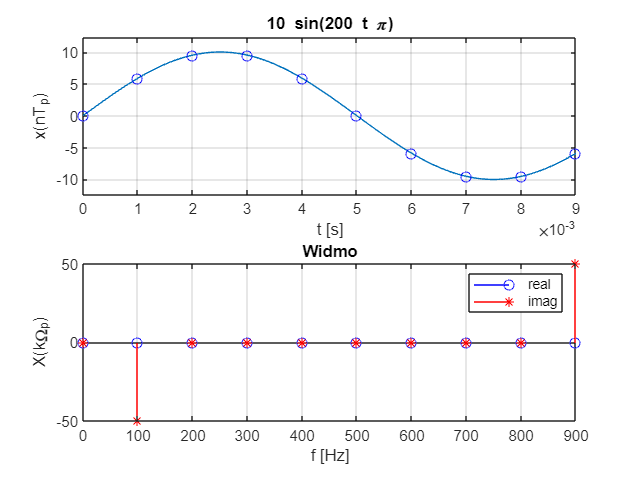

figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
stem(fn, real(Xk),'ob'); grid on, hold on
stem(fn, imag(Xk),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

Utworzyć wektor fn = [0: N-1]*f1 i ustalić go jako oś x

### Zadanie 3

clear all; close all
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
w1 = 2*pi*f1;
x1 = A1*sin(w1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);%<uzupelnij>;
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   1.2341e-13



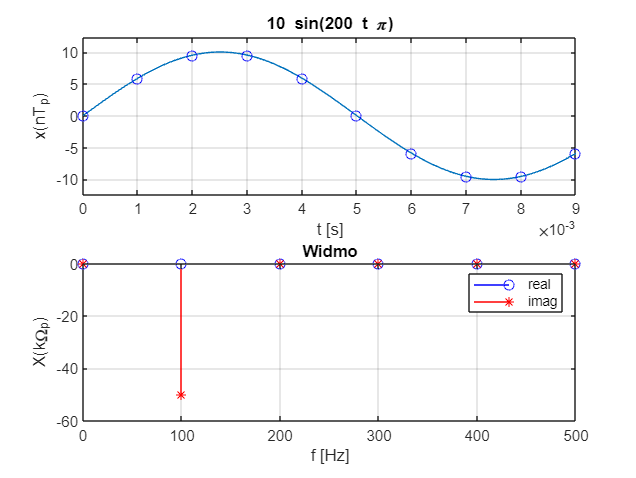

figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
stem(fn(1:N/2+1), real(Xk(1:N/2+1)),'ob'); grid on, hold on
stem(fn(1:N/2+1), imag(Xk(1:N/2+1)),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

Wykorzystując twierdzenie o próbkowaniu ograniczam wyświetlane częstotliwości do połowy częstotliwości próbkowania.

### Zadanie 4

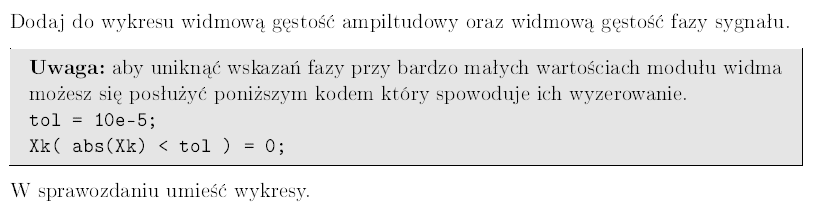

clear all; close all;
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
w1 = 2*pi*f1;
x1 = A1*sin(w1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);%<uzupelnij>;
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   1.2341e-13



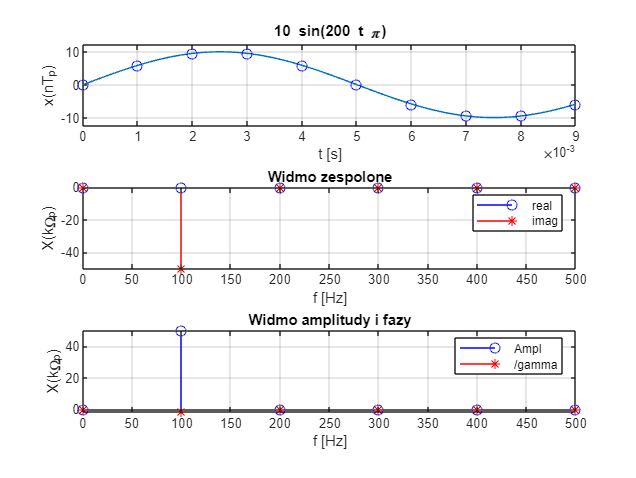

figure;
subplot(3,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(3,1,2)
stem(fn(1:N/2+1), real(Xk(1:N/2+1)),'ob'); grid on, hold on
stem(fn(1:N/2+1), imag(Xk(1:N/2+1)),'*r');
title('Widmo zespolone');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

subplot(3,1,3)
tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;
stem(fn(1:N/2+1), abs(Xk(1:N/2+1)),'ob'); grid on, hold on
stem(fn(1:N/2+1), angle(Xk(1:N/2+1)),'*r');
title('Widmo amplitudy i fazy');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('Ampl','/gamma')

### Zadanie 5

N = 15

clear all; close all;
syms t w
N = 15; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
w1 = 2*pi*f1;
x1 = A1*sin(w1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);%<uzupelnij>;
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   5.1371e-13



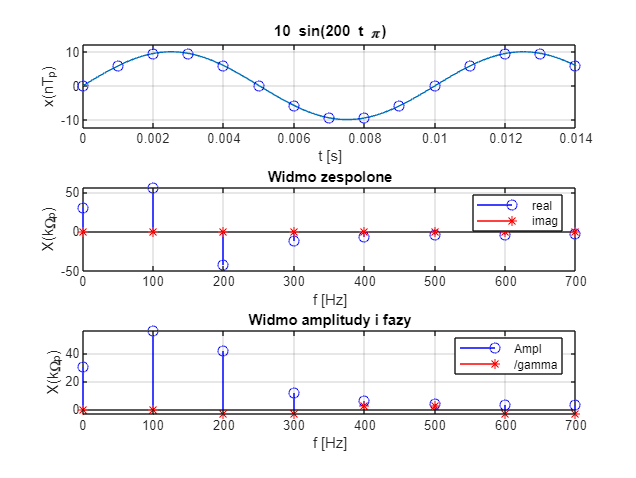

figure;
subplot(3,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(3,1,2)

f_max = idivide(int32(N),2)+1;
stem(fn(1:f_max), real(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), imag(Xk(1:f_max)),'*r');
title('Widmo zespolone');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

subplot(3,1,3)
tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;
stem(fn(1:f_max), abs(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), angle(Xk(1:f_max)),'*r');
title('Widmo amplitudy i fazy');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('Ampl','/gamma')

N =  20

clear all; close all;
syms t w
N = 20; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
w1 = 2*pi*f1;
x1 = A1*sin(w1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);%<uzupelnij>;
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   1.4883e-12



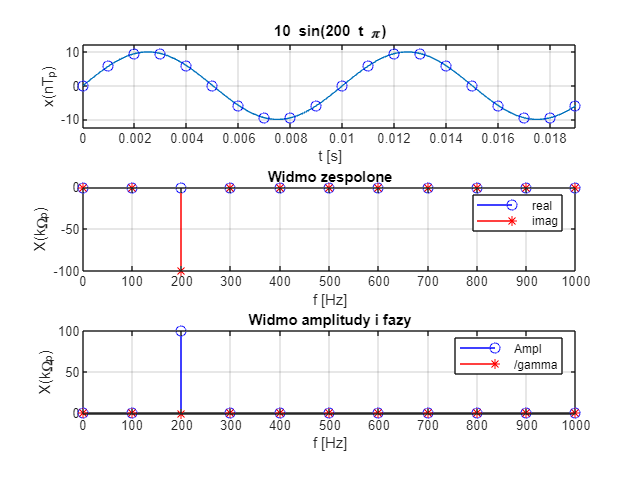

figure;
subplot(3,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(3,1,2)
stem(fn(1:N/2+1), real(Xk(1:N/2+1)),'ob'); grid on, hold on
stem(fn(1:N/2+1), imag(Xk(1:N/2+1)),'*r');
title('Widmo zespolone');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')


subplot(3,1,3)
tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;
stem(fn(1:N/2+1), abs(Xk(1:N/2+1)),'ob'); grid on, hold on
stem(fn(1:N/2+1), angle(Xk(1:N/2+1)),'*r');
title('Widmo amplitudy i fazy');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('Ampl','/gamma')

Jeżeli okno próbkowania nie obejmuje dokładnie okresu lub jego wielokrotności to powoduje to znieształcenie widma wynikowego.

### Zadanie 6

clear all; close all;
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 150; %Hz
w1 = 2*pi*f1;
x1 = A1*sin(w1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);%<uzupelnij>;
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   1.9041e-13



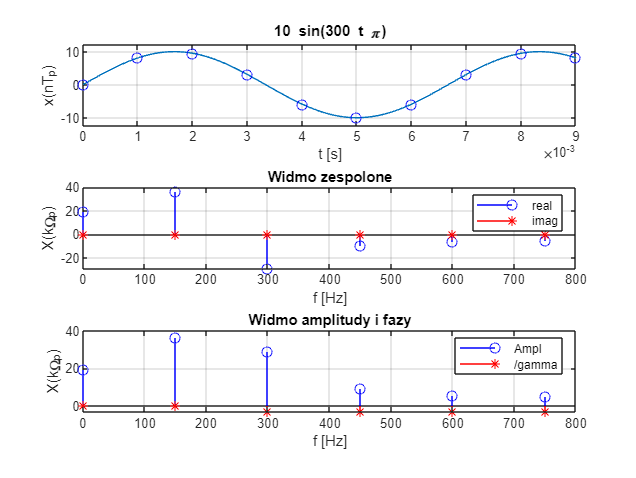

figure;
subplot(3,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(3,1,2)

f_max = idivide(int32(N),2)+1;
stem(fn(1:f_max), real(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), imag(Xk(1:f_max)),'*r');
title('Widmo zespolone');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

subplot(3,1,3)
tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;
stem(fn(1:f_max), abs(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), angle(Xk(1:f_max)),'*r');
title('Widmo amplitudy i fazy');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('Ampl','/gamma')

Okno próbkowania nie zawiera całkowitej wielkorotności okresów funkcji i zachodzi zjawisko przecieku widma

### Zadanie 7

Triang(n)

clear all; close all;
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 150; %Hz
w1 = 2*pi*f1;
x1 = A1*sin(w1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
okno = triang(N)';
xn = double(subs(x,t,tn));
xn = xn.*okno;
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);%<uzupelnij>;
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   6.8418e-14



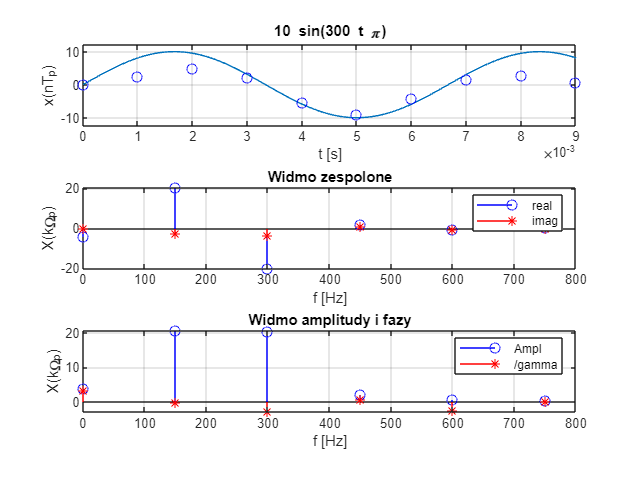


figure;
subplot(3,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(3,1,2)
f_max = idivide(int32(N),2)+1;
stem(fn(1:f_max), real(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), imag(Xk(1:f_max)),'*r');
title('Widmo zespolone');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

subplot(3,1,3)
tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;
stem(fn(1:f_max), abs(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), angle(Xk(1:f_max)),'*r');
title('Widmo amplitudy i fazy');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('Ampl','/gamma')

window(@gausswin, N, 2.5)

clear all; close all;
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 150; %Hz
w1 = 2*pi*f1;
x1 = A1*sin(w1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
okno = window(@gausswin, N, 2.5)';
xn = double(subs(x,t,tn));
xn = xn.*okno;
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);%<uzupelnij>;
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   6.6485e-14



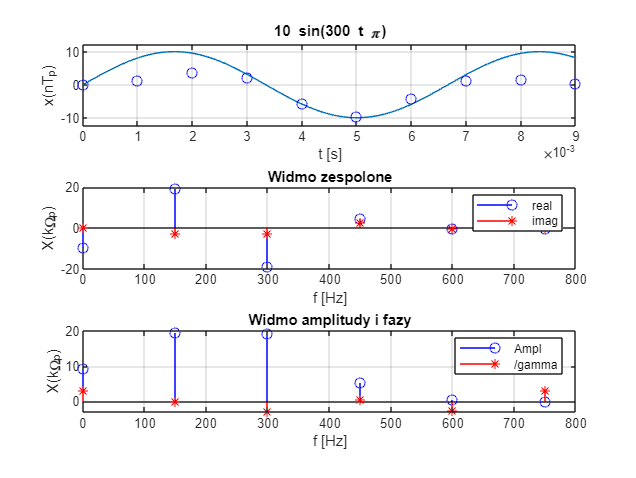


figure;
subplot(3,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(3,1,2)
f_max = idivide(int32(N),2)+1;
stem(fn(1:f_max), real(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), imag(Xk(1:f_max)),'*r');
title('Widmo zespolone');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

subplot(3,1,3)
tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;
stem(fn(1:f_max), abs(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), angle(Xk(1:f_max)),'*r');
title('Widmo amplitudy i fazy');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('Ampl','/gamma')

Przy tak małej ilości próbek oba zaproponowane okna są tak samo złe

bohmanwin(N)

clear all; close all;
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 150; %Hz
w1 = 2*pi*f1;
x1 = A1*sin(w1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
okno = bohmanwin(N)';
xn = double(subs(x,t,tn));
xn = xn.*okno;
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);%<uzupelnij>;
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   6.2843e-14



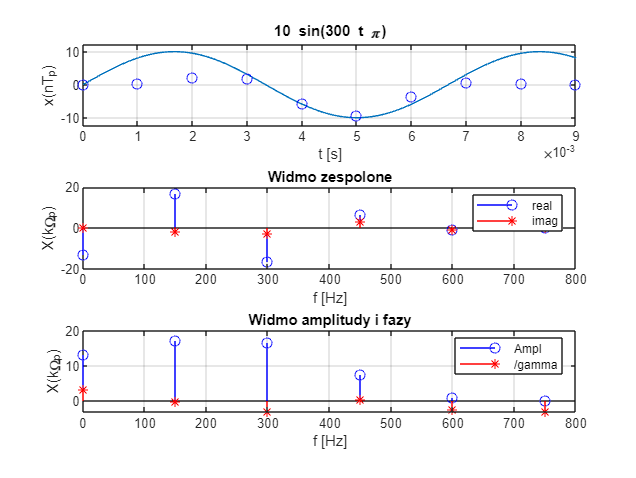


figure;
subplot(3,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(3,1,2)
f_max = idivide(int32(N),2)+1;
stem(fn(1:f_max), real(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), imag(Xk(1:f_max)),'*r');
title('Widmo zespolone');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

subplot(3,1,3)
tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;
stem(fn(1:f_max), abs(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), angle(Xk(1:f_max)),'*r');
title('Widmo amplitudy i fazy');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('Ampl','/gamma')

Dla żadnego okienkowania nie udało się uzyskać widma przypominającym widmo prawdziwe

### Zadanie 8

clear all; close all;
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A1 = 10; f1 = 150; %Hz
A2 = 5; f2 = 200;
w1 = 2*pi*f1; w2 = 2*pi*f2;
x1 = A1*sin(w1*t) + A2*sin(w2*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   1.4110e-13



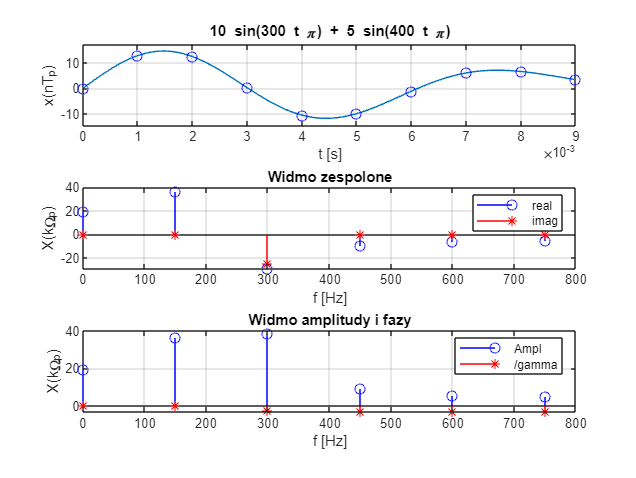


figure;
subplot(3,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(3,1,2)
f_max = idivide(int32(N),2)+1;
stem(fn(1:f_max), real(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), imag(Xk(1:f_max)),'*r');
title('Widmo zespolone');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

subplot(3,1,3)
tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;
stem(fn(1:f_max), abs(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), angle(Xk(1:f_max)),'*r');
title('Widmo amplitudy i fazy');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('Ampl','/gamma')

Przesunięte

clear all; close all;
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A1 = 10; f1 = 150; %Hz
A2 = 5; f2 = 200;
w1 = 2*pi*f1; w2 = 2*pi*f2;
x1 = A1*sin(w1*(t-2*Tp)) + A2*sin(w2*(t-2*Tp));
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp((-1i*2*pi*k*n)/N);
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   1.3995e-13



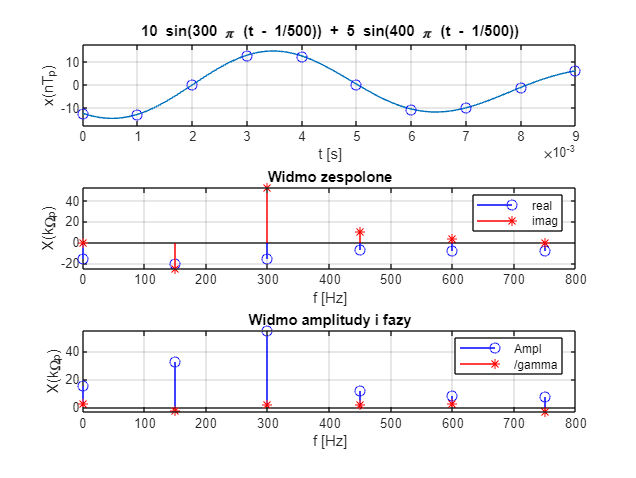


figure;
subplot(3,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(3,1,2)
f_max = idivide(int32(N),2)+1;
stem(fn(1:f_max), real(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), imag(Xk(1:f_max)),'*r');
title('Widmo zespolone');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

subplot(3,1,3)
tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;
stem(fn(1:f_max), abs(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), angle(Xk(1:f_max)),'*r');
title('Widmo amplitudy i fazy');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('Ampl','/gamma')

### Zadanie ZD

clear all; close all;
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A1 = 10; f1 = 100; %Hz
w1 = 2*pi*f1;
x1 = A1*sin(w1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
fn = [0: N-1]*f1;
xn = double(subs(x,t,tn));
DFT_M = dftmtx(N);
Xk = xn*DFT_M;
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   8.8818e-15




figure;
subplot(3,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(3,1,2)
f_max = idivide(int32(N),2)+1;
stem(fn(1:f_max), real(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), imag(Xk(1:f_max)),'*r');
title('Widmo zespolone');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

subplot(3,1,3)
tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;
stem(fn(1:f_max), abs(Xk(1:f_max)),'ob'); grid on, hold on
stem(fn(1:f_max), angle(Xk(1:f_max)),'*r');
title('Widmo amplitudy i fazy');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('Ampl','/gamma')